# Q1

We have additive uncertainty, and one of our results is that a system with unstructured additive uncertainty is RS $\iff \|W_AKS\|_\infty<1$.  Here $W_A$ is simply the constant 1, so the infinity norm is simply of $KS$ is simplity scaled by unity.

s = tf("s");
G = [1/(s+1) 2/(s+3);1/(s+1) 1/(s+1)];
K = eye(2);
S = eye(2)-feedback(G*K,eye(2));
gamma = 1/norm(K*S,'inf')

gamma = 0.8684

# Q2

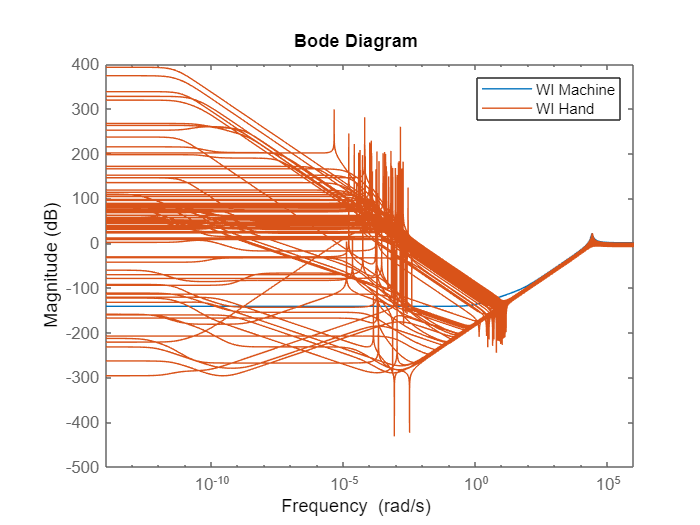

s= tf("s");
A = ureal('A',0.7,'Range',[0.4,1]);
zeta = ureal('zeta',0.31,'Range',[0.02, 0.6]);
w = ureal('w',4100*2*pi,'Range',[4000*2*pi, 4200*2*pi]);
P_unc = 3.8 * 10^9 * (1/s^2 + A/(s^2+2*zeta*w*s+w^2));
P_unc = usample(P_unc, 100);
P_nom = (3.8*10^9)/s^2;
[P,info] = ucover(P_unc,P_nom,2);
WI_machine = info.W1;
WI_hand = (P_unc - P_nom)/P_nom;
bodemag(WI_machine, WI_hand)
legend("WI Machine", "WI Hand")

# Q3

# b

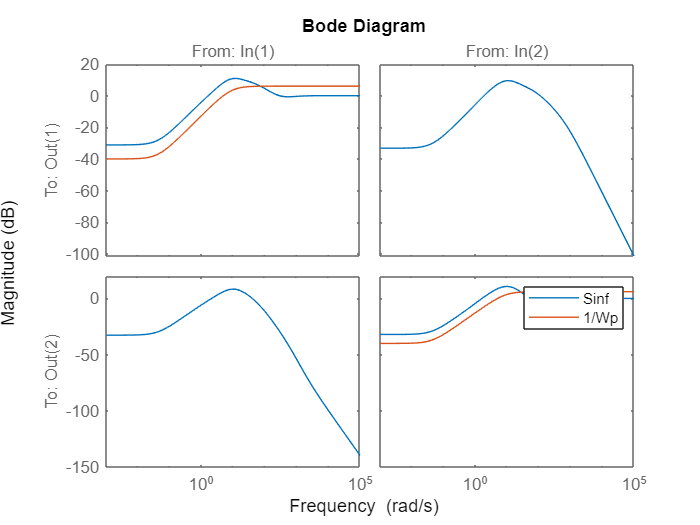

s = tf("s");
a = ureal('a', 1, 'Percentage', 20);
G = [1/(s+a) 2/(s+3);1/(s+a) 1/(s+a)];
WA = 0.2*((s+100)/10/(s+10))*eye(2);
Wu = (1/50)*eye(2);
Wp = makeweight(100, 5, 1/2)*eye(2);

%fit uncertainty weight
Gunc = usample(G,100);
Gnom = G.NominalValue;
[P,info] = ucover(Gunc,Gnom,2);
Wo = info.W1*eye(2);

systemnames = 'Gnom WA Wp Wu Wo'; %Block name only
inputvar = '[duA{2};duO{2};w{2};u{2}]';
outputvar = '[WA;Wo;Wu;Wp;-w-duO-Gnom]'; %Strangely, the system outputs are just the name
input_to_Gnom = '[u+duA]';
input_to_Wo = '[Gnom]';
input_to_WA = '[-w-duO-Gnom]';
input_to_Wp = '[w+Gnom+duO]';
input_to_Wu = '[u+duA]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;
[Kinf,CL,GAM] = hinfsyn(P,2,2);
Sinf = inv(eye(2)+Gnom*Kinf);
bodemag(Sinf, inv(Wp))
legend("Sinf","1/Wp")

# c

delta1 = ultidyn('delta1',[1,1]);
delta2 = ultidyn('delta2',[1,1]);
delta_diag = [delta1 0; 0 delta2];
delta_full = ultidyn('delta_full',[2,2]);
G_struct = (eye(2)+delta_diag*Wo)*Gnom;
G_unstruct = (eye(2)+delta_full*Wo)*Gnom;

%structured uncertainty
systemnames = 'G_struct Wp Wu'; %Block name only
inputvar = '[w{2};u{2}]';
outputvar = '[Wu;Wp;-w-G_struct]'; %Strangely, the system outputs are just the name
input_to_G_struct = '[u]';
input_to_Wp = '[w+G_struct]';
input_to_Wu = '[u]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P_struct = sysic;

N_struct = lft(P_struct, Kinf);
perfmarg_struct = robuststab(N_struct);
mu_struct = 1/perfmarg_struct.LowerBound

mu_struct = 0.9061

perfmarg_struct = robustperf(N_struct);
mu_struct = 1/perfmarg_struct.LowerBound

mu_struct = 5.7586


%unstructured uncertainty
systemnames = 'G_unstruct Wp Wu'; %Block name only
inputvar = '[w{2};u{2}]';
outputvar = '[Wu;Wp;-w-G_unstruct]'; %Strangely, the system outputs are just the name
input_to_G_unstruct = '[u]';
input_to_Wp = '[w+G_unstruct]';
input_to_Wu = '[u]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P_unstruct = sysic;

N_unstruct = lft(P_unstruct, Kinf);
perfmarg_unstruct = robuststab(N_unstruct);
mu_unstruct = 1/perfmarg_unstruct.LowerBound

mu_unstruct = 0.9061

perfmarg_unstruct = robustperf(N_unstruct);
mu_unstruct = 1/perfmarg_unstruct.LowerBound

mu_unstruct = 5.7593

# Q4

H2 Controller

s = tf("s");
G = (s+1)/(s^2+0.2*s+5);
WI = (10*s+10)/(s+1000);
Wu = 0.01;
Wp = makeweight(100,100,1/2);
systemnames = 'G Wu Wp WI'; %Block name only
inputvar = '[du;r;u]';
outputvar = '[WI;Wp;Wu;r-G-du]'; %Strangely, the system outputs are just the name
input_to_G = '[u]';
input_to_Wp = '[r-G-du]';
input_to_Wu = '[u]';
input_to_WI = '[G]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;
[K2,CL,GAM] = h2syn(P,1,1);

delta = ultidyn('delta',[1,1]);
G_hat = G*(1+WI*delta);

systemnames = 'G_hat Wu Wp';
inputvar = '[r;u]';
outputvar = '[Wp;Wu;r-G_hat]';
input_to_G_hat = '[u]';
input_to_Wp = '[r-G_hat]';
input_to_Wn = '[u]';
cleanupsysic = 'yes';
P_hat = sysic;

N_hat = lft(P_hat,K2); 
[STABMARG2,WCU] = robuststab(N_hat);
mu_2 = 1/STABMARG2.LowerBound

mu_2 = 0.5167

mu<1, has robust stability

perfmarg_2 = robustperf(N_hat);
mu_2 = 1/perfmarg_2.LowerBound

mu_2 = 2.1484

mu>1, no robust performance

H$\infty$ Controller

[Kinf,CL,GAM] = hinfsyn(P,1,1);
N_hat = lft(P_hat,Kinf);
[STABMARGinf,WCU] = robuststab(N_hat);
mu_inf = 1/STABMARGinf.LowerBound

mu_inf = 0.6972

mu<1, has robust stability.

perfmarg_inf = robustperf(N_hat);
mu_inf = 1/perfmarg_inf.LowerBound

mu_inf = 1.6117

mu>1, no robust performance.

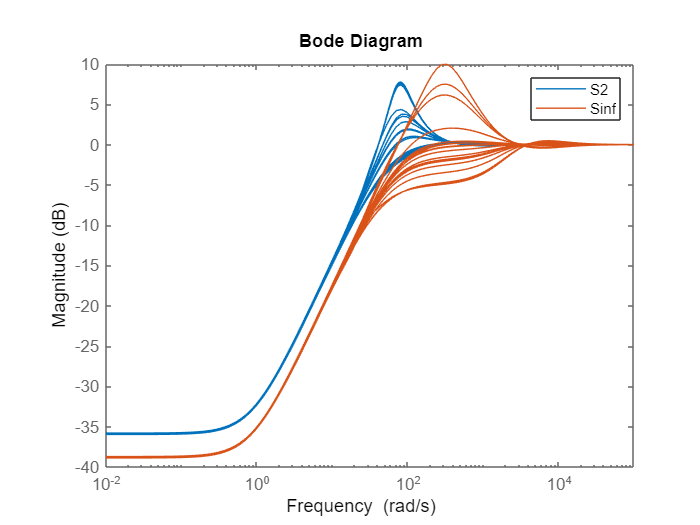

S2 = inv(1+G_hat*K2);
Sinf = inv(1+G_hat*Kinf);
bodemag(S2,Sinf)
legend("S2","Sinf")

# Q5

s = tf("s");
Gm = 1/s;
Gs = 1/10/s;
Ge = ((0.16*s^3)+240*s)/((0.008*s^4)+(0.48*s^3)+144*s);
Gh = 1152/((4*s^4)+(48*s^3)+(240*s^2)+576*s+576);

systemnames = 'Gh Gm Gs Ge'; %Block name only
inputvar = '[wh;we;fm;fs]';
outputvar = '[Gm;Gs;Ge]'; %Strangely, the system outputs are just the name
input_to_Gh = '[wh]';
input_to_Gm = '[Gh-fm]';
input_to_Gs = '[Ge-fs]';
input_to_Ge = '[we]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;
P_ss = ss(P)

P_ss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12       x13       x14
   x1        -12      -7.5      -4.5     -2.25         0         0         0         0         0         0         0         0         0         0
   x2          8         0         0         0         0         0         0         0         0         0         0         0         0         0
   x3          0         4         0         0         0         0         0         0         0         0         0         0         0         0
   x4          0         0         2         0         0         0         0         0         0         0         0         0         0         0
   x5          0         0         0    0.0625         0         0         0         0         0         0         0         0         0         0
   x6          0         0         0         0         0       -60  3.02e-14    -35.16         0      

[A,B,C,D] = ssdata(P_ss);
B1 = B(:,1:3) %14x3

B1 =      8     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     2     0
     0     0     0
     0     0     0
     0     0     0
     0     8     0


B2 = B(:,4) %14x1

B2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


C1 = C(1:2,:) %2x14

C1 =          0         0         0         0    9.0000         0         0         0         0         0         0         0   -1.0000         0
         0         0         0         0         0         0    0.0625         0    2.9297         0         0         0         0   -0.4000


C2 = C(3,:) %1x14

C2 =          0         0         0         0         0         0         0         0         0    2.5000         0    7.3242         0         0


D12 = zeros(2,1)

D12 =      0
     0


D22 = 0

D22 = 0

D21 = zeros(1,3)

D21 =      0     0     0


D21 is all 0, which make the ARE unsolvable.